# Lysosome Stats

Use this script to generate the figures presented in the manuscript. 

Requires the following variables to be loaded:

## Load Variables

Change directory to the Lysosome Analysis Folder 

load lysosomesVL.mat
load cellT.mat
load lysT.mat

% set(groot, 'defaultAxesFontSize', 16);
mmSetFigPublication(18)

## Calculate lysosome stats 

### Test for normality of lysosomal volumes

warning off
for n=unique(lysT.Cell)'

    x = lysT.Volume(lysT.Cell==n);
    if numel(x)>3
        [h, p] = adtest(x);

        if ~h
            fprintf('%s has normally distributed volumes. p=%1.2f',n,p)
        end
    end
end
warning on

- no lysosome volumes are normally distributed. Probably best to discuss their median

## Calcuate lysosome stats per cell

### Include TraceSum

s = groupsummary(lysT,"Cell",["sum","median","mean","std"],["Volume","TraceSum"]);
s.Properties.VariableNames = {'Object',...
    'LysCount', 'LysTotalVol','LysMedianVol',...
    'LysMeanVol','LysStdVol','LysTraceVol','LysTraceMedian','LysTraceMean','LysTraceStd'}

### Lysosome Volume Only — group summary by cell

In this table, I calculate the stats of the lysosomes per cells. 

s = groupsummary(lysT,"Cell",["sum","median","mean","std","max","min"],"Volume");
s.Properties.VariableNames = {'Object',...
    'LysCount', 'LysTotalVol','LysMedianVol','LysMeanVol','LysStdVol','LysMaxVol','LysMinVol'}

- **LysCount**: total number of lysosomes found in a cell

- **LysTotalVolume**: summed volume of all lysosomes found in a cell

- **LysMedianVol**: median volume of lysosomes found in a cell

- **LysTraceVol**: summed volume of cross-sectional traces found in a cell (should be roughly equivalent to LysTotalVolume)

- **LysTraceMedian**: The median cross-sectional area of a lysosome in a given cell

### Add percent volume

Percent volume is total lysosome volume divided by cell volume


$$\textrm{LysCellRatio}=\frac{\textrm{Total}\;\textrm{Lysosome}\;\textrm{Volume}\;}{\textrm{Cell}\;\textrm{Volume}}$$


cellT = join(cellT,s);
% cellT = sortrows(cellT,"Object");
cellT.LysCellRatio = cellT.LysTotalVol./ cellT.VolMan

- I and III healthy cells are about the same size

- I dying cell is larger than the other two cells

groupsummary(cellT,["Health","Type"],["min" "max"],"VolMan")
disp(ans)

groupsummary(lysT,["Health"],["min" "max" "median"],"Volume")

    Health     Type    GroupCount    min_VolMan    max_VolMan
    _______    ____    __________    __________    __________

    early      I           1           279.24        279.24  
    early      II          4           279.95          1631  
    early      x           1           504.47        504.47  
    healthy    I           9           417.67        1326.3  
    healthy    II          5           399.03         969.8  
    healthy    III         7           162.57        812.06  
    healthy    IV          4           107.98        605.31  
    late       x           2           200.03        323.02  



disp(ans)

    Health     GroupCount    min_Volume    max_Volume    median_Volume
    _______    __________    __________    __________    _____________

    healthy       2726       3.2295e-05      23.316        0.0085102  
    early          914       1.1326e-05      39.143         0.021659  
    late           187       0.00051769      1.7164        0.0033834  



## Visualization

### Plot: Lys Count and Median Lys Volume

likely a function of volume

figure(Visible="on")

clf
tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;
y = cellT.LysCount;

y2 = cellT.LysMedianVol;
y2_label = ("Median Lys Vol")

% y2 = cellT.LysCellRatio;

nexttile
hold on

y2_label = "Median Lys Vol"

boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
% boxchart(g,y,GroupByColor=g,Notch="off")


ylabel("Lysosome Count")
xlabel("")
grid on


nexttile

swarmchart(g,y2, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
hold on
boxchart(g,y2,"BoxFaceColor","#0072BD",Notch="off")

xlabel("cell type")
grid on

ylabel("Lysosome Volume")
% sgtitle("Lysosome metrics per cell")

- Dying cells have the fewest number of lysosomes

- Dying cells have the lowest ratio of lysome volume to cell volume

- Large range in median volumes for Dying, I, and II

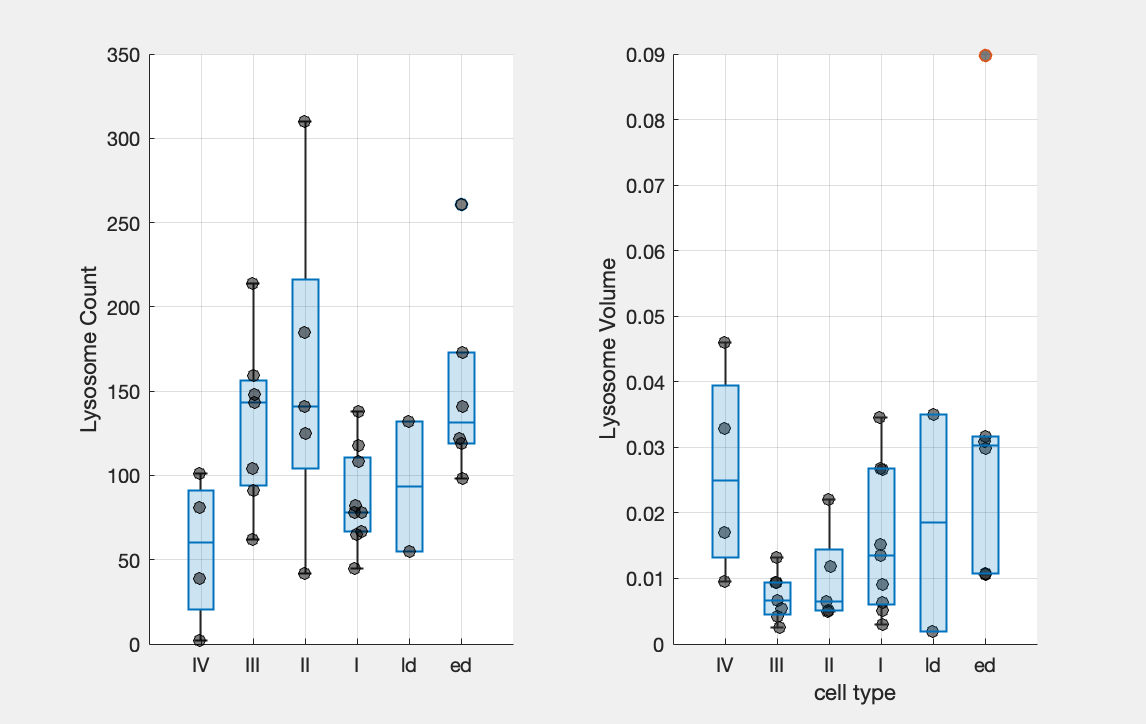

mmfig

g = cellT.PlotSort;
y = cellT.LysCellRatio;

hold on

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
% boxchart(g,y,GroupByColor=g,Notch="off")


ylabel("Lysosome Cell Ratio")
xlabel("")
grid on

exportgraphics(gcf,fullfile(project_folder,"Figures","lys-boxchart.pdf"),Resolution=600)

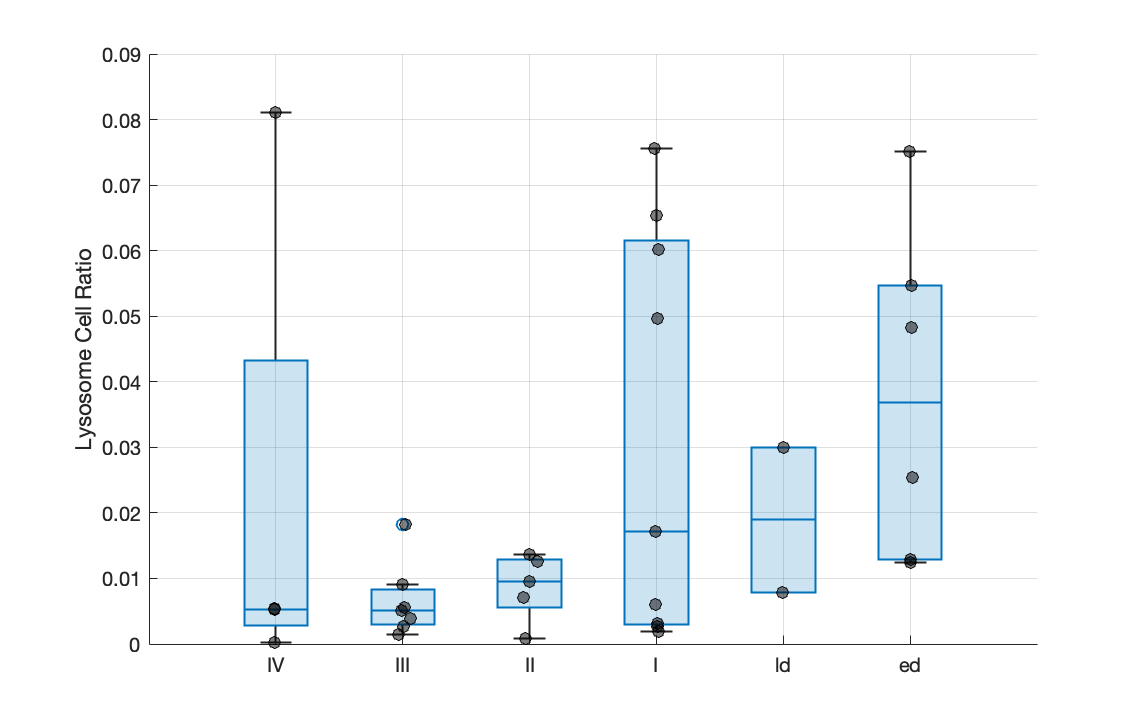

exportgraphics(gcf,fullfile(project_folder,"Figures","lys-boxchart.png"),Resolution=600)

## Other Fields

## Volume Analysis

### Cell stats

cell_stats = groupsummary(cellT,"PlotSort",["min" "max"],"VolMan")
disp(cell_stats)

### Visualize

mmfig;

tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');

    PlotSort    GroupCount    min_VolMan    max_VolMan
    ________    __________    __________    __________

      IV            4           107.98        605.31  
      III           7           162.57        812.06  
      II            5           399.03         969.8  
      I             9           417.67        1326.3  
      ld            2           200.03        323.02  
      ed            6           279.24          1631  



g = cellT.PlotSort;
y = cellT.VolMan;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel('Cell Volume (µm^3)')

### Lysosome Total volume per cell

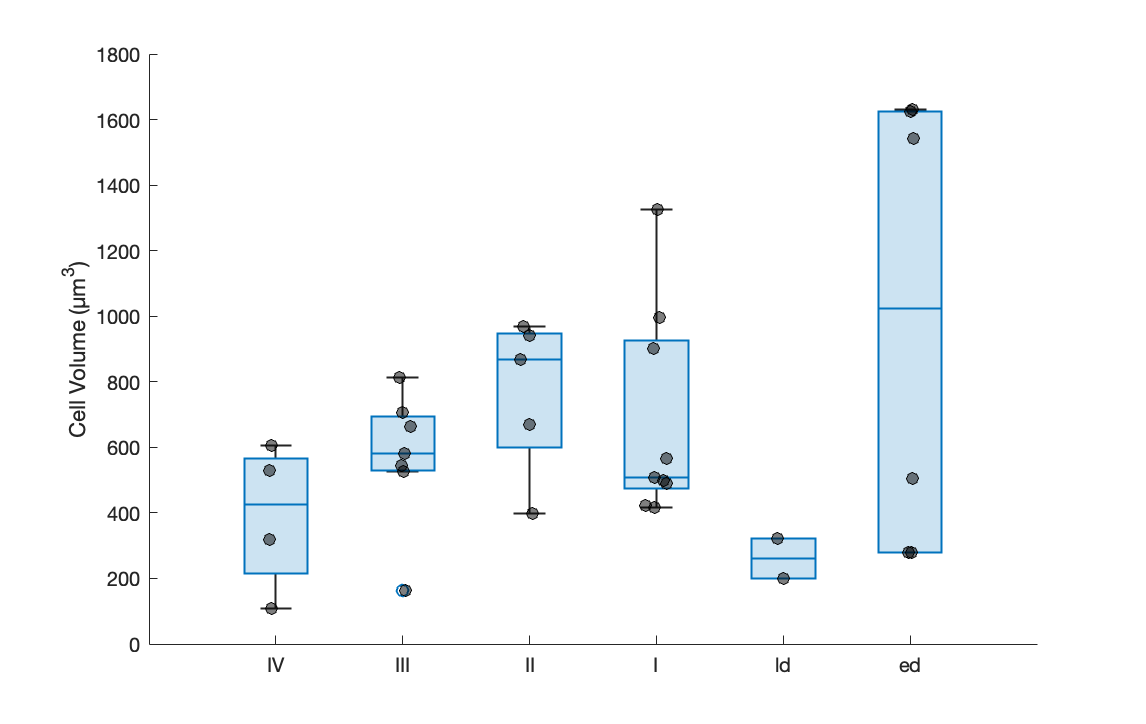

mmfig;

tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;

y = cellT.LysTotalVol;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel("Total Volume of Lysosome per cell (µm^3)")

# Discontinued

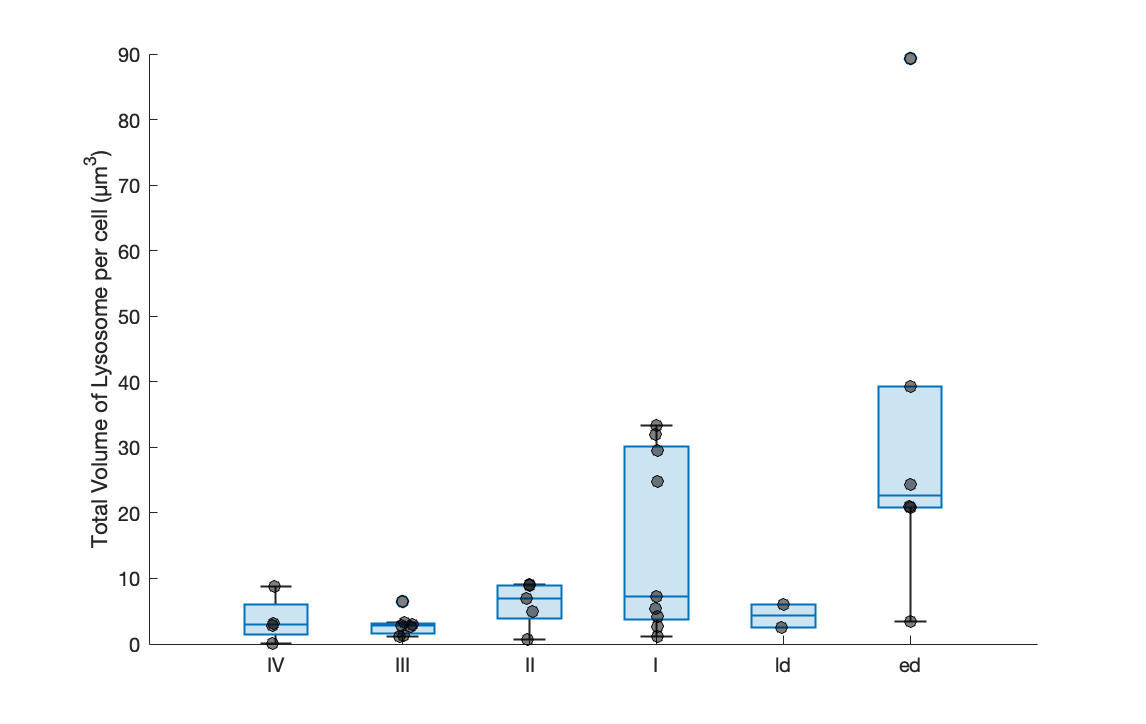

mmFigure;
% tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;
y = cellT.LysCellRatio;


y2 = cellT.LysMedianVol;
y2_label = ("Median Lys Vol")


% y2 = cellT.LysCellRatio;

% nexttile
hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
% boxchart(g,y,GroupByColor=g,Notch="off")

## Lysosome Volume distributions

mmFigure;
boxchart(lysT.PlotSort, lysT.Volume)

s = groupsummary(lysT,"PlotSort",["mean", "std"],["Volume","TraceSum","TraceMax"])
% figure(Visible="on")
clf
% bar(s.PlotSort,s.mean_Volume)
% hold on
x = s.PlotSort;
y = s.mean_Volume;
e = s.std_Volume;
errorbar(x,y,e)
title('Mean Lys Volume by Cell Type')

% figure(Visible="on")
clf
boxchart(lysT.PlotSort,lysT.TraceMax)



## Cell type II

Gardner Altman Plots

la = lysT.Health == "healthy" & lysT.Type == "II";
x = lysT.Volume(la);
la = lysT.Health == "dying" & lysT.Type == "II";
y = lysT.Volume(la);

clf
gardnerAltmanPlot(x,y);

## Statistics

figure(Visible="on")

### Test for normality

groupsummary(lysT,"PlotSort",@adtest,"Volume")

- none of the volumes are normally distributed

### Lysosome Count

y = cellT.LysCount;
g = cellT.PlotSort;
[p,tbl,stats] = kruskalwallis(y,g)
mmfig
multcompare(stats)

### Lysosome Median Volume

III is different from 1

y = cellT.LysMedianVol;
g = cellT.PlotSort;
[p,tbl,stats] = kruskalwallis(y,g)
multcompare(stats)

### Lysosome Mean Volume

y = cellT.LysMeanVol;
g = cellT.PlotSort;
[p,tbl,stats] = kruskalwallis(y,g)
multcompare(stats)

[p,tbl,stats] = kruskalwallis(y,g)
multcompare(stats)

#### distributions

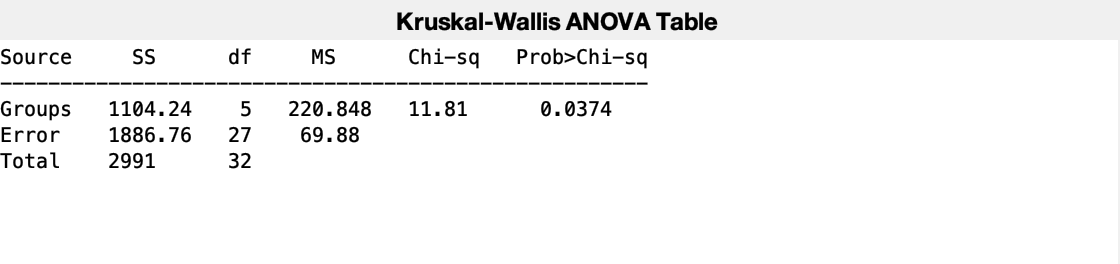

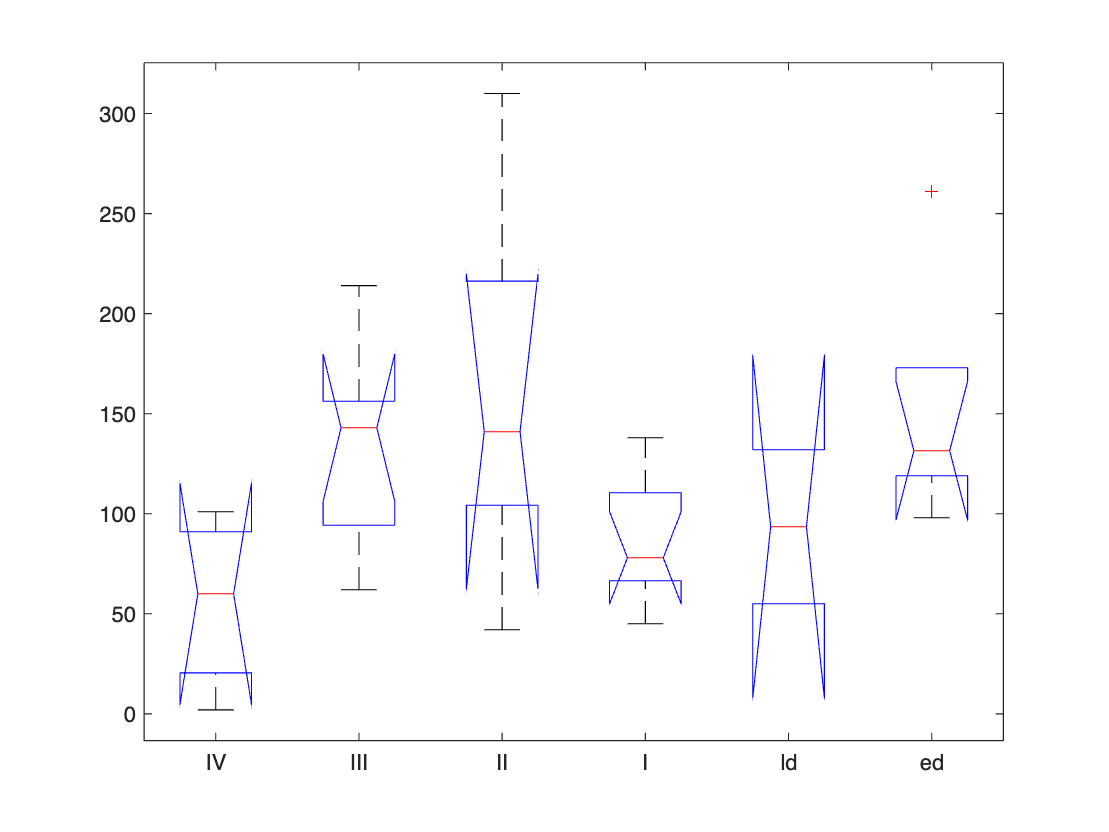

p = 0.0374

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[1.1042e+03]}    {[ 5]}    {[220.8483]}    {[ 11.8140]}    {[     0.0374]}
    {'Error' }    {[1.8868e+03]}    {[27]}    {[ 69.8799]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[      2991]}    {[32]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {6×1 cell}
            n: [4 7 5 9 2 6]
       source: 'kruskalwallis'
    meanranks: [7.2500 21 22.3000 12 13.5000 23.0833]
         sumt: 12


% groupName = "Health"
% dataName = cellT.Properties.VariableNames;

% la2 = cellT.Health 

ans =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


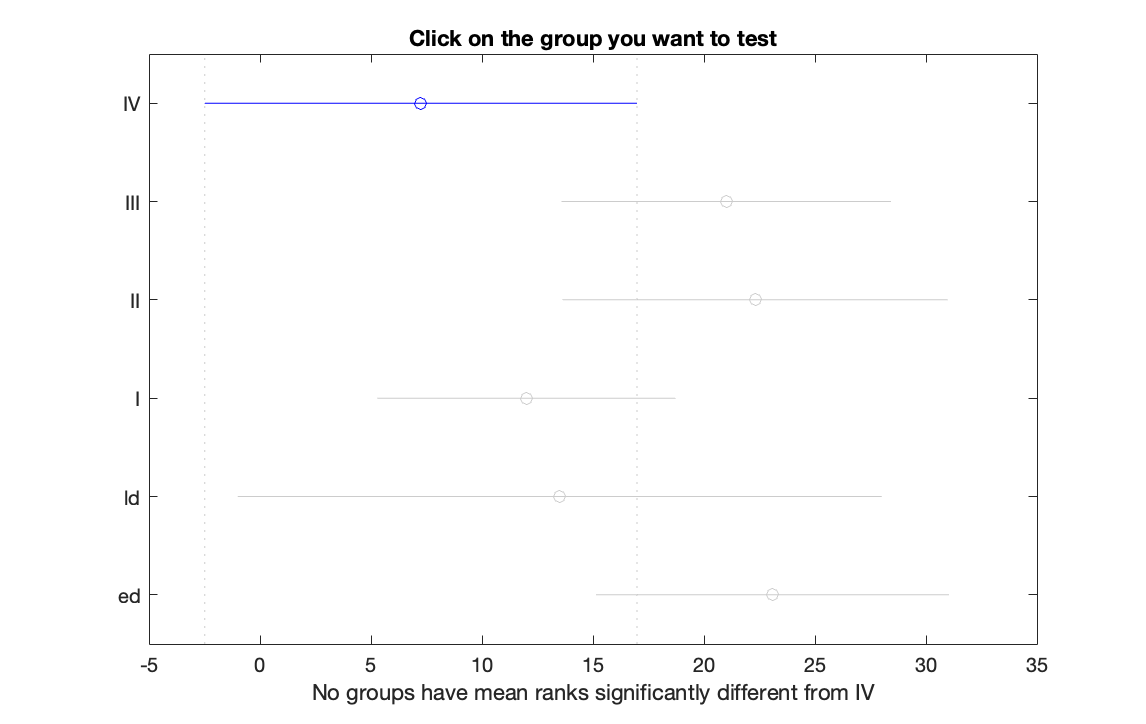

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


ans =     1.0000    2.0000  -31.0183  -13.7500    3.5183    0.2068
    1.0000    3.0000  -33.5316  -15.0500    3.4316    0.1856
    1.0000    4.0000  -21.3059   -4.7500   11.8059    0.9644
    1.0000    5.0000  -30.1096   -6.2500   17.6096    0.9760
    1.0000    6.0000  -33.6173  -15.8333    1.9506    0.1134
    2.0000    3.0000  -17.4321   -1.3000   14.8321    0.9999
    2.0000    4.0000   -4.8843    9.0000   22.8843    0.4352
    2.0000    5.0000  -14.5897    7.5000   29.5897    0.9282
    2.0000    6.0000  -17.4111   -2.0833   13.2445    0.9989
    3.0000    4.0000   -5.0671   10.3000   25.6671    0.3958


% la = true(height(cellT),1);

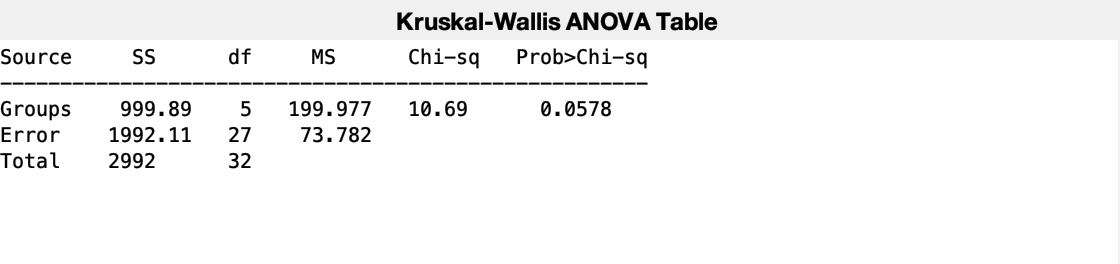

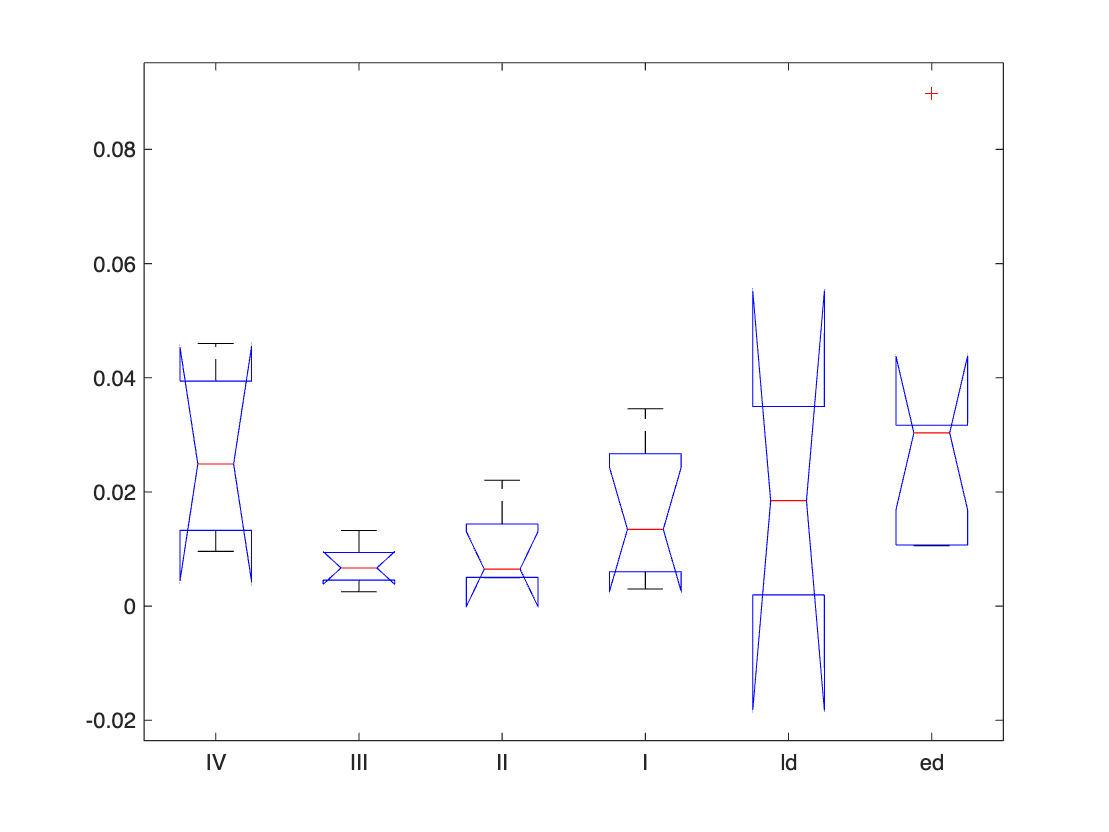

p = 0.0578

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[  999.8873]}    {[ 5]}    {[199.9775]}    {[ 10.6940]}    {[     0.0578]}
    {'Error' }    {[1.9921e+03]}    {[27]}    {[ 73.7820]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[      2992]}    {[32]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {6×1 cell}
            n: [4 7 5 9 2 6]
       source: 'kruskalwallis'
    meanranks: [24.5000 10.1429 12.4000 16.7778 16 24.5000]
         sumt: 0


% la = ~contains(cellT.Object,'AP37');
la = cellT.Type == "II";
y = cellT.LysMeanVol(la);
g = cellT.Health(la);

clf

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


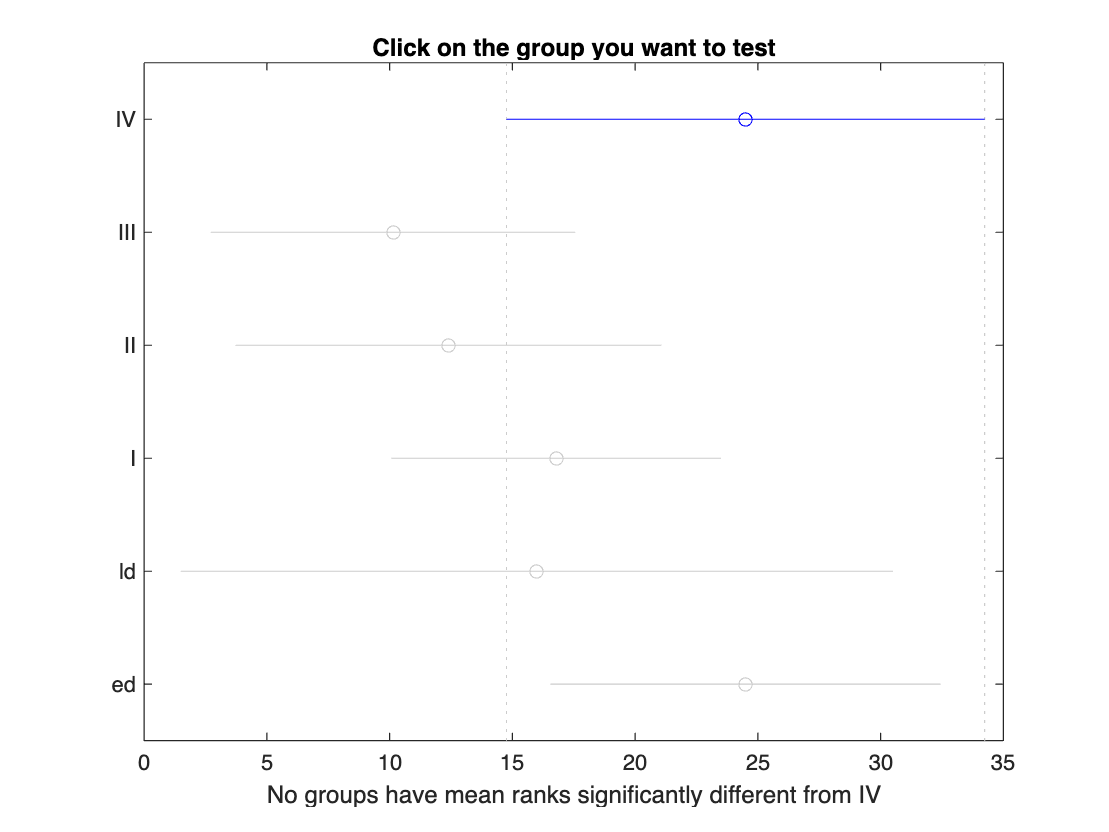

ans =     1.0000    2.0000   -2.9141   14.3571   31.6284    0.1672
    1.0000    3.0000   -6.3847   12.1000   30.5847    0.4237
    1.0000    4.0000   -8.8365    7.7222   24.2809    0.7690
    1.0000    5.0000  -15.3636    8.5000   32.3636    0.9131
    1.0000    6.0000  -17.7869         0   17.7869    1.0000
    2.0000    3.0000  -18.3919   -2.2571   13.8776    0.9987
    2.0000    4.0000  -20.5215   -6.6349    7.2517    0.7501
    2.0000    5.0000  -27.9506   -5.8571   16.2363    0.9747
    2.0000    6.0000  -29.6875  -14.3571    0.9732    0.0816
    3.0000    4.0000  -19.7474   -4.3778   10.9919    0.9655


swarmchart(g,y,"filled","MarkerFaceAlpha",0.75)

hold on
boxchart(g,y,"BoxFaceColor",'k',BoxFaceAlpha=.1)
colormap parula

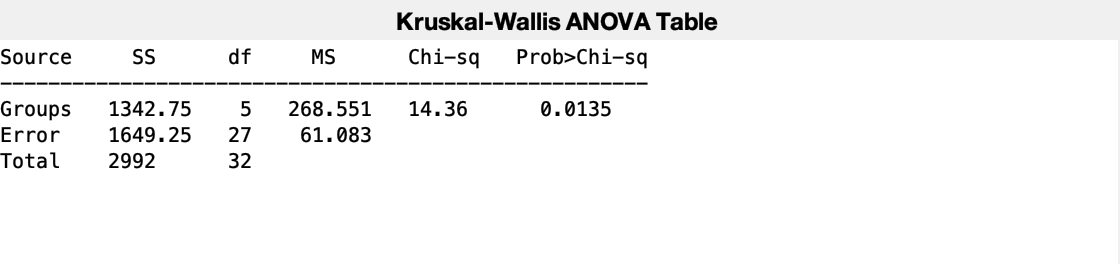

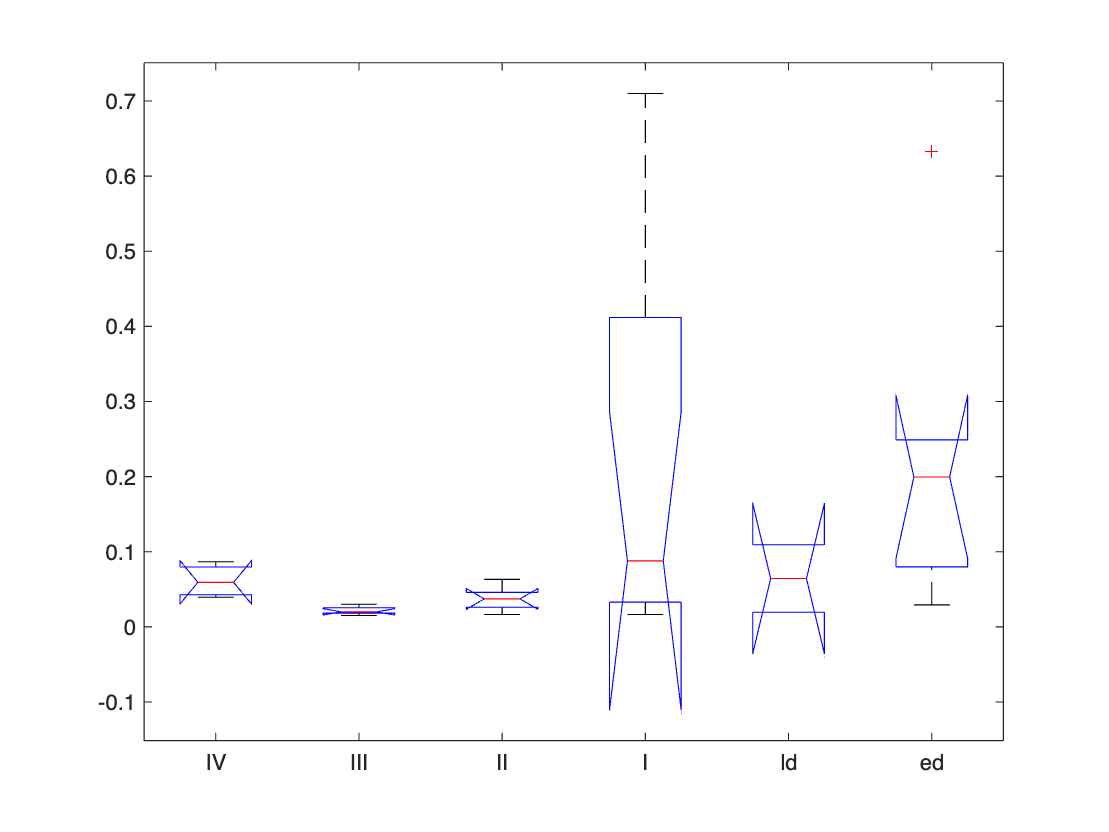

p = 0.0135

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[1.3428e+03]}    {[ 5]}    {[268.5508]}    {[ 14.3610]}    {[     0.0135]}
    {'Error' }    {[1.6492e+03]}    {[27]}    {[ 61.0832]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[      2992]}    {[32]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {6×1 cell}
            n: [4 7 5 9 2 6]
       source: 'kruskalwallis'
    meanranks: [19.5000 6.8571 13 21.2222 15.5000 24.6667]
         sumt: 0


y = cellT.LysCellRatio;
g = cellT.Type

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


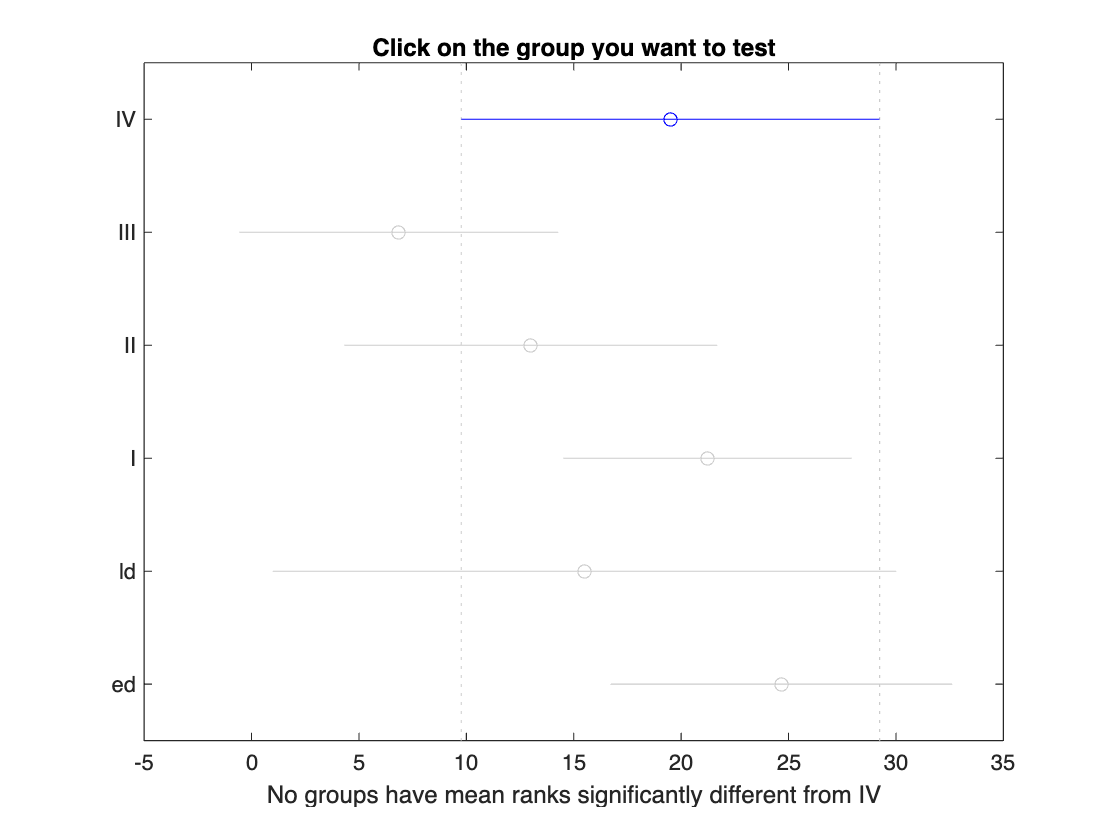

ans =     1.0000    2.0000   -4.6284   12.6429   29.9141    0.2945
    1.0000    3.0000  -11.9847    6.5000   24.9847    0.9174
    1.0000    4.0000  -18.2809   -1.7222   14.8365    0.9997
    1.0000    5.0000  -19.8636    4.0000   27.8636    0.9969
    1.0000    6.0000  -22.9536   -5.1667   12.6202    0.9625
    2.0000    3.0000  -22.2776   -6.1429    9.9919    0.8876
    2.0000    4.0000  -28.2517  -14.3651   -0.4785    0.0377
    2.0000    5.0000  -30.7363   -8.6429   13.4506    0.8755
    2.0000    6.0000  -33.1399  -17.8095   -2.4791    0.0120
    3.0000    4.0000  -23.5919   -8.2222    7.1474    0.6484


[p,h,stats] = anovan(y,{g}');

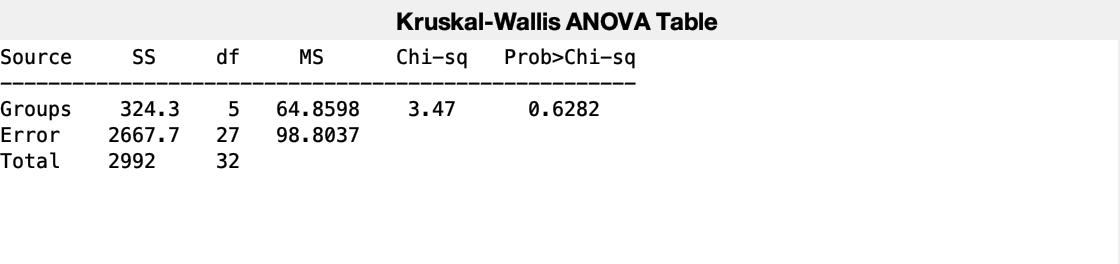

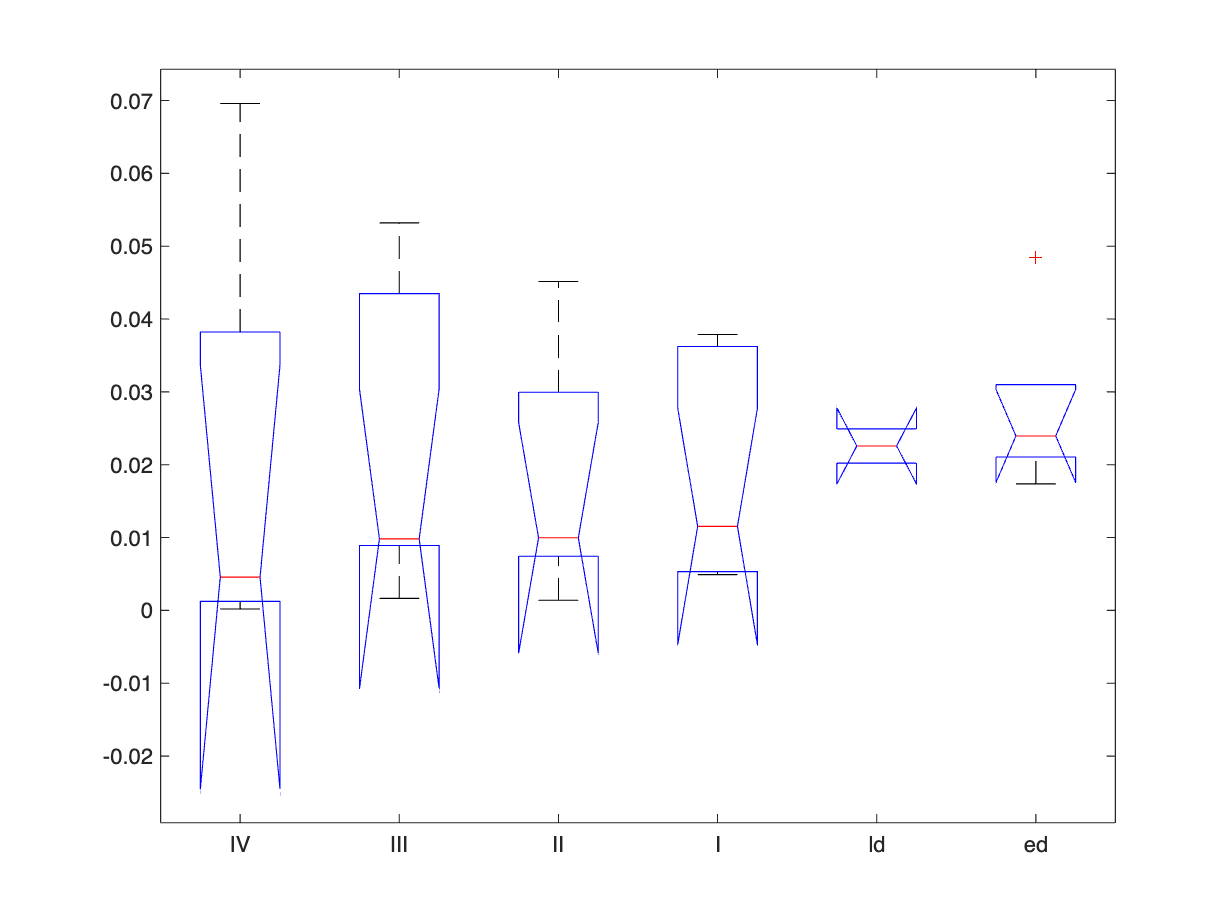

p = 0.6282

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[  324.2992]}    {[ 5]}    {[ 64.8598]}    {[  3.4684]}    {[     0.6282]}
    {'Error' }    {[2.6677e+03]}    {[27]}    {[ 98.8037]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[      2992]}    {[32]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {6×1 cell}
            n: [4 7 5 9 2 6]
       source: 'kruskalwallis'
    meanranks: [11.7500 16.7143 15.8000 15.8889 20.5000 22.3333]
         sumt: 0


% groupName = "Health"
% dataName = cellT.Properties.VariableNames;

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


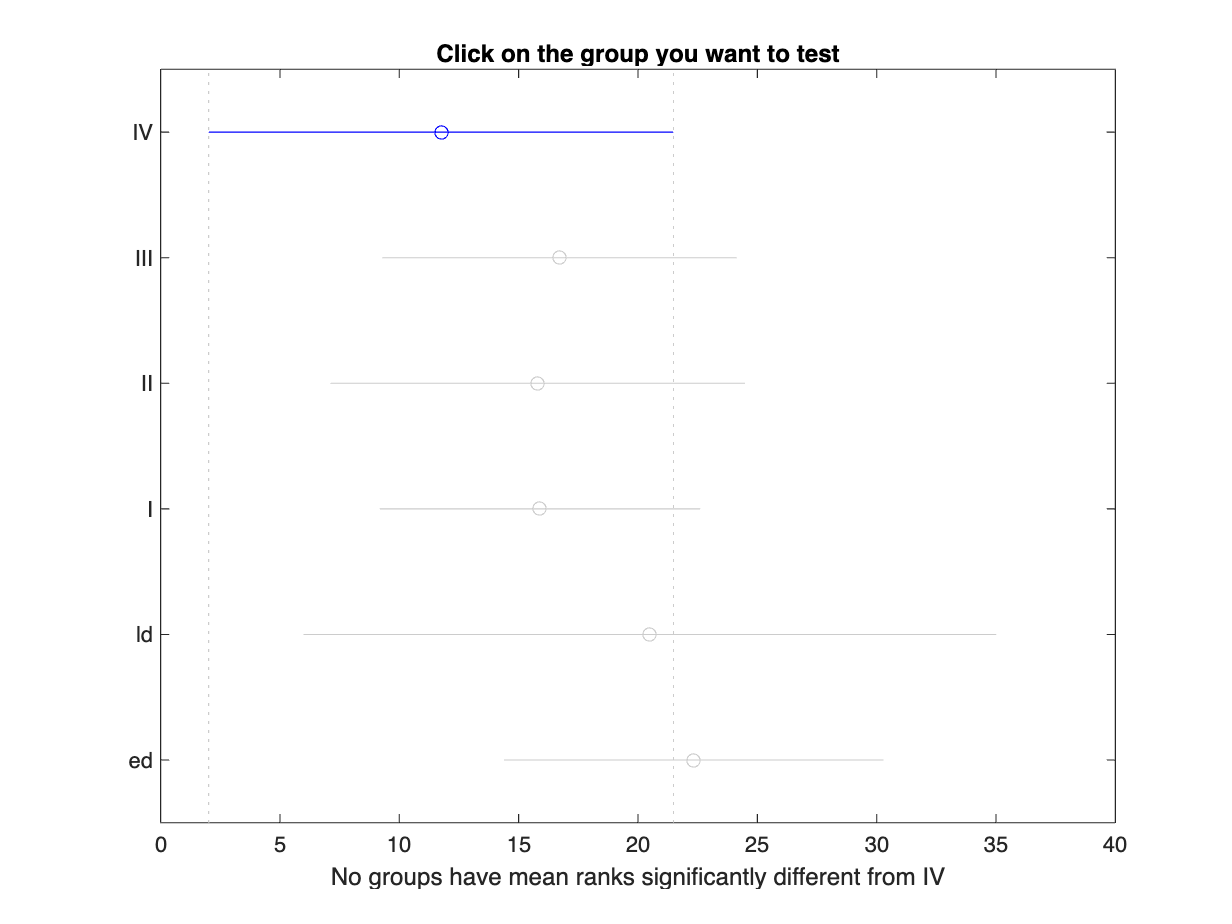

ans =     1.0000    2.0000  -22.2355   -4.9643   12.3069    0.9641
    1.0000    3.0000  -22.5347   -4.0500   14.4347    0.9893
    1.0000    4.0000  -20.6976   -4.1389   12.4198    0.9805
    1.0000    5.0000  -32.6136   -8.7500   15.1136    0.9027
    1.0000    6.0000  -28.3702  -10.5833    7.2036    0.5347
    2.0000    3.0000  -15.2205    0.9143   17.0490    1.0000
    2.0000    4.0000  -13.0612    0.8254   14.7120    1.0000
    2.0000    5.0000  -25.8791   -3.7857   18.3077    0.9966
    2.0000    6.0000  -20.9494   -5.6190    9.7113    0.9028
    3.0000    4.0000  -15.4585   -0.0889   15.2807    1.0000


la = cellT.Type =="II";

% la2 = cellT.Health 
% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');


y = cellT.LysCellRatio(la);
g = cellT.PlotSort(la);
[p,h,stats] = anovan(y,{g});
figure(Visible="on")
[results] = multcompare(stats)

% groupName = "Health"
% dataName = cellT.Properties.VariableNames;
la = cellT.Type =="II";
y = cellT.LysCount(la);
g = cellT.Health(la);
[p,h,stats] = anovan(y,{g});
figure(Visible="on")
[results] = multcompare(stats)

figure(Visible="on")

g = 33×1 categorical array
     I 
     I 
     I 
     I 
     I 
     I 
     I 
     I 
     I 
     I 
     II 
     II 
     II 
     II 
     II 
     II 
     II 
     II 
     II 
     III 
     III 
     III 
     III 
     III 
     III 
     III 
     IV 
     IV 
     x 
     x 


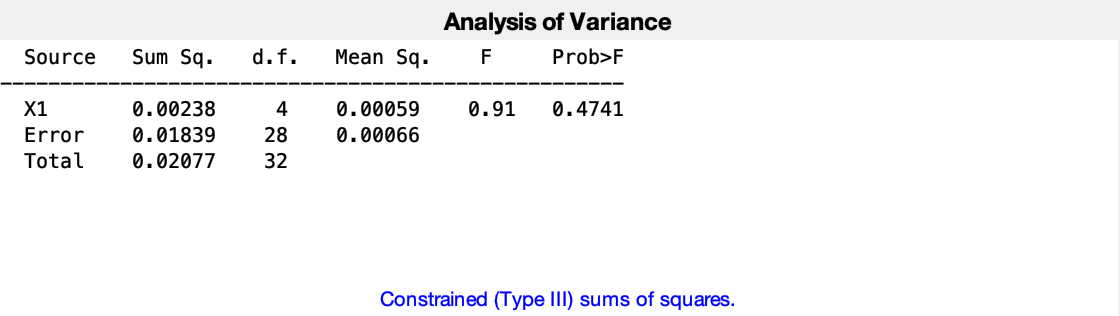

tiledlayout("vertical")


nexttile
boxchart(cellT.PlotSort,cellT.LysTotalVol)
ylabel("Tot Vol Lys")

nexttile
boxchart(cellT.PlotSort,cellT.LysMeanVol)
ylabel("Median Vol Lys")

anovan()

### Compare methods of volume calculation

figure(Visible="on")
tiledlayout("vertical")


nexttile
boxchart(cellT.PlotSort,cellT.LysTotalVol)
ylabel("Tot Volume")

nexttile
boxchart(cellT.PlotSort,cellT.LysTraceVol)
ylabel("Trace Volume ")
sgtitle("Comparison of Volume to Summed areas")

- We find that the distribution of the summed volume of cross-sectional traces  is roughly equivalent to summed total volume, as it should be

- This confirms that we are calculating volume correctly

### Display stats grouped by health

Metric comparisons. 

A note on Lysosome volumes. I calcuated lysome volume using two methods. In the fist method, volumes were calculate from 3D alphashapes rendered from the traces. In the second method, I estimated volume by summing the cross-sectional 2D areas from each trace of a lysome. I expect these volumes to be roughly equivalent. 

figure(Visible="on")
tiledlayout("vertical")
y = ["LysCellRatio","LysTotalVol","LysMedianVol","Volume","SurfaceArea"];
yl = ["Lys/Cell Ratio", "Lys Tot Vol", "Lys Median Vol","Cell vol", "Cell SA"];
for n=1:numel(y)
    nexttile
    boxchart(cellT.Type,cellT.(y(n)),GroupByColor=cellT.Health)
    ylabel(yl(n))
    legend(categories(cellT.Health))
end
sgtitle('Lysosome distribution by health')

% figure(Visible="on")
clf
boxchart(cellT.Type,cellT.LysCount,GroupByColor=cellT.Health)
ylabel('Lys Count')
legend(categories(cellT.Health))

clf
boxchart(cellT.Type,cellT.LysMedianVol,GroupByColor=cellT.Health)
ylabel('Lys Median Volume')
legend(categories(cellT.Health))

### Lysosome metrics

stats_cell = groupsummary(cellT,"PlotSort",["mean","std"],["Volume","SurfaceArea","SAV"])
stats_lys = groupsummary(lysT,"PlotSort",["mean","std"],["Volume","SurfaceArea","SAV"])

- lysosome size: III < Healthy I < Dying I

- dying lysosomes have a smaller SAV (more spherical?)

figure;
tiledlayout(1,3)

nexttile
errorbar(stats_cell.PlotSort,stats_cell.mean_Volume,stats_cell.std_Volume)
ylabel('Volume')
xlabel('Cell Type')
title('Mean Cell Volume')

nexttile
errorbar(stats_cell.PlotSort,stats_cell.mean_SurfaceArea,stats_cell.std_SurfaceArea)
ylabel('Surface Area')
xlabel('Cell Type')
title('Mean Cell Surface Area')

nexttile
errorbar(stats_lys.PlotSort,stats_lys.mean_Volume,stats_lys.std_Volume)
ylabel('Volume')
xlabel('Cell Type')
title('Mean Lysosome Volume')

Death Associated Type I cells;

cellT.PlotSort2 = cellT.PlotSort;
cellT.PlotSort2 = addcats(cellT.PlotSort2,'I+','After','I');
cellT.PlotSort2([4 5 7]) = "I+";

lysT.PlotSort2 = lysT.PlotSort;
lysT.PlotSort2 = addcats(lysT.PlotSort2,'I+','After','I');

cellIDs = cellT.CellID([4 5 7])'

for n=cellIDs
%     cellID = cellT.CellID(n);
    la = lysT.CellID == n;
    lysT.PlotSort2(la) = 'I+';
end

stats_cell = groupsummary(cellT,"PlotSort2",["mean","std"],["Volume","SurfaceArea","SAV"]);
stats_lys = groupsummary(lysT,"PlotSort2",["mean","std"],["Volume","SurfaceArea","SAV"]);

figure;
tiledlayout(1,3)

nexttile
errorbar(stats_cell.PlotSort2,stats_cell.mean_Volume,stats_cell.std_Volume)
ylabel('Mean Volume')
xlabel('Cell Type')
title('Cell')

nexttile
errorbar(stats_cell.PlotSort2,stats_cell.mean_SurfaceArea,stats_cell.std_SurfaceArea)
ylabel('Mean Surface Area')
xlabel('Cell Type')
title(' Cell')

nexttile
errorbar(stats_lys.PlotSort2,stats_lys.mean_Volume,stats_lys.std_Volume)
ylabel('Mean Volume')
xlabel('Cell Type')
title('Lysosome')

figure;
boxchart(cellT.PlotSort2,cellT.lys_vol)
ylabel('Lys / Cell Vol Ratio')

### Boxchart

figure;
tiledlayout(1,2)
nexttile
boxchart(lysT.Type, lysT.Volume,'Notch','on')
grid minor
ylabel('Volume')

nexttile
boxchart(lysT.Type, lysT.SurfaceArea,'Notch','on')
grid minor
ylabel('Surface Area')

### Swarmchart

figure;
tiledlayout(1,2)
nexttile
swarmchart(lysT,"Type","Volume")
nexttile
swarmchart(lysT,"Type","SurfaceArea")

### Histogram

figure
x = lysT.Volume(lysT.Group=="healthy");
histogram(x,20);
hold on
x = lysT.Volume(lysT.Group=="dying");
histogram(x,20)